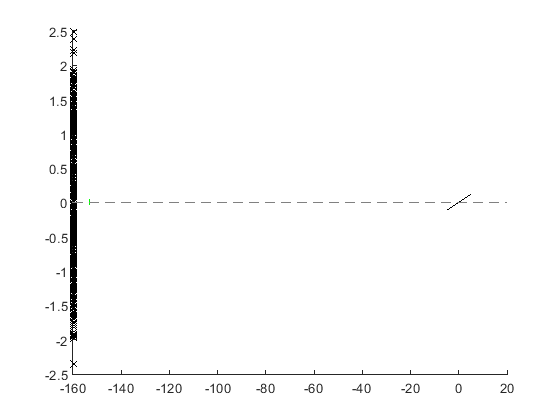

tic
%clear all;

%plot setup with
beamon=false;

%Goebel specification
NRays=1E4; %number of rays per source
Ngoebel=1E4; %Number of sources on Goebel mirror

delta=0.03; %divergence angle
fwhm=1.35; %fwhm of Goebel source distr.
ds=160; %distance to sources on sarm
dgoebelsslit=7; %distance Goebel to source slit
gammas=90; %Goebel mirror rotation [deg] (90=not rotated)



%slit specifications
wsslit=0.1; %width source slit

%detectorsarm speficications
dd=0;
wd=10;
NPixels=100;

%angles
alpha=1.4 ; %Source arm angle


%items calculations
gammasslit=90; gammad=alpha;
dsslit=ds-dgoebelsslit;

%Create setup
setup=startsetup();

setup=add_goebel(setup,ds,gammas,fwhm,Ngoebel,NRays,delta);
setup=add_sslit(setup,dsslit,wsslit, gammasslit);
setup=add_detector_sarm(setup,dd,wd, gammad,NPixels);


%plot basic, non-rotated setup with beams off or on depending on beamon
fig1=plot_setup(setup,0,0,beamon,dd+1);

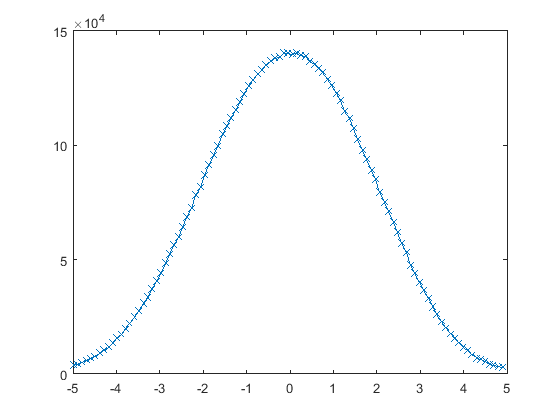


%measure Detector on Sourcearm
[a,I]=Scan_DetectorImageSarm(setup,1);


toc

Elapsed time is 44.413331 seconds.
